%% =========================================================================
%  Effective Reproduction Number (R_e) vs Infection and Interventions
%  =========================================================================
%  D_I   = phi + eta + rho_M*M + mu + gamma*rho * I_T*(2+sigma*I_T)/(1+sigma*I_T)^2
%  R_e   = epsilon / (D_I*(epsilon+mu)) * ( delta_e + beta_Q*sigma_L*alpha*K ...
%          / (delta*(mu_L+sigma_L)) * (1 - mu/psi) )
%  =========================================================================

clear; clc; close all;

%% --------------------- 1. Parameter Values -------------------------------
% (Choose biologically plausible values; adjust as needed for your model)
phi     = 0.01;      % natural birth rate
mu      = 0.01;      % natural death rate
eta     = 0.08;      % disease-induced death rate
epsilon = 0.001;     % progression rate (latent -> infectious)
delta_1 = 0.3;       % transmission rate at DFE
delta_e = 0.5;       % effective transmission rate (can vary with interventions)
beta_Q  = 0.0001;    % transmission from quarantined class
sigma_L = 0.1;       % rate of loss of quarantine
alpha   = 0.5;       % modification parameter
K       = 20500;     % carrying capacity / scaling factor
delta   = 0.2;       % recovery rate
mu_L    = 0.05;      % quarantine-related death rate
psi     = 0.5;       % waning immunity rate
rho_M   = 0.03;      % contribution of M to D_I
gamma   = 0.1;       % saturation coefficient
rho     = 0.2;       % saturation coefficient
sigma   = 0.05;      % saturation parameter for I_T

%% --------------------- 2. Compute Common Terms ---------------------------
% At DFE: D_I0 = phi + eta + mu
D_I0    = phi + eta + mu;

% Common factor inside the parentheses 
% FIX: Added 'K' to match the formula in the header and the calculations in Figures 1 & 2
common_term = (beta_Q * sigma_L * alpha * K) / (delta * (mu_L + sigma_L)) ...
              * (1 - mu / psi);

fprintf('D_I at DFE (no infection)  = %.4f\n\n', D_I0);

D_I at DFE (no infection)  = 0.1000



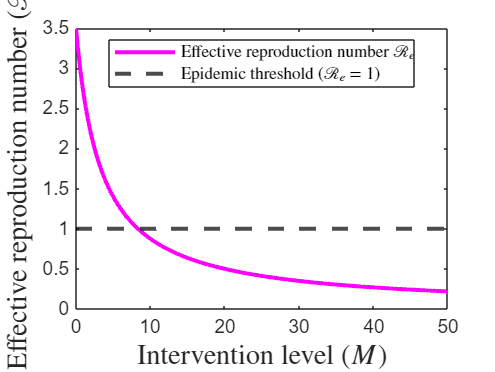


%% --------------------- 3. R_e as a function of I_T -----------------------
% Show how R_e decreases as I_T increases (saturation effect in D_I)
I_T_vals = linspace(0, 200, 500);   % range of infectious individuals
Re_vs_IT = zeros(size(I_T_vals));

for k = 1:length(I_T_vals)
    IT = I_T_vals(k);
    
    % D_I depends on I_T (with M = 0 for simplicity here)
    D_I = phi + eta + mu + gamma * rho * IT * (2 + sigma * IT) ...
          / (1 + sigma * IT)^2;
    
    % R_e with current D_I (simplified using common_term)
    Re_vs_IT(k) = (epsilon / (D_I * (epsilon + mu))) * (delta_e + common_term);
end

%% --------------------- 4. R_e as a function of M -------------------------
% Show how R_e decreases as M (e.g., intervention / media / treatment) increases
M_vals   = linspace(0, 50, 500);
Re_vs_M  = zeros(size(M_vals));

for k = 1:length(M_vals)
    M = M_vals(k);
    
    % D_I depends on M (with I_T = 0 for simplicity here)
    D_I = phi + eta + rho_M * M + mu;
    
    % R_e with current D_I (simplified using common_term)
    Re_vs_M(k) = (epsilon / (D_I * (epsilon + mu))) * (delta_e + common_term);
end

%% --------------------- 5. Plotting (Separate Figures) --------------------

% --- Figure 1: R_e vs I_T ---
%figure('Position',[100 100 800 600], 'Name', 'R_e vs I_T');
%plot(I_T_vals, Re_vs_IT, 'b-', 'LineWidth', 2); hold on;
%yline(1,  'k--', 'LineWidth', 2, 'DisplayName', 'Threshold (R_e = 1)');

% UPDATED: LaTeX formatting for math symbols
%xlabel('$I_T$ (Infectious individuals)', 'Interpreter', 'latex', 'FontSize', 14);
%ylabel('$R_e$', 'Interpreter', 'latex', 'FontSize', 14);
%title('$R_e$ vs $I_T$ ($M = 0$)', 'Interpreter', 'latex', 'FontSize', 16);

%legend('Location','best', 'FontSize', 12);
%grid on;

% --- Figure 2: R_e vs M ---
figure('Position',[200 150 800 600], 'Name', 'R_e vs M');
plot(M_vals, Re_vs_M, 'm-', 'LineWidth', 2); hold on;
yline(1,  'k--', 'LineWidth', 2, 'DisplayName', 'Threshold (R_e = 1)');

xlabel('Intervention level ($M$)', ...
    'Interpreter', 'latex', 'FontSize', 14);

ylabel('Effective reproduction number ($\mathcal{R}_e$)', ...
    'Interpreter', 'latex', 'FontSize', 14);
legend({'Effective reproduction number $\mathcal{R}_e$', ...
        'Epidemic threshold ($\mathcal{R}_e = 1$)'}, ...
       'Interpreter', 'latex', 'Location', 'best');

%title('$R_e$ vs $M$', 'Interpreter', 'latex', 'FontSize', 16);

%legend('Location','best', 'FontSize', 12);
%grid on;

%% --- Figure 3: Contour plot of R_e vs D_I and \delta_e ---
figure('Position',[300 200 800 600], 'Name', 'R_e contours vs D_I and delta_e');

% Create a 2D grid of D_I and delta_e
DI_grid_vals = linspace(0.1, 1.0, 50);      
delta_e_vals = linspace(0.1, 1.0, 50);   
[DI_grid, de_grid] = meshgrid(DI_grid_vals, delta_e_vals);

% Compute R_e for each combination of D_I and delta_e
Re_grid = (epsilon ./ (DI_grid .* (epsilon + mu))) .* (de_grid + common_term);

% Display the range of R_e values
fprintf('R_e ranges from %.4f to %.4f\n', min(Re_grid(:)), max(Re_grid(:)));

R_e ranges from 0.3135 to 3.9530


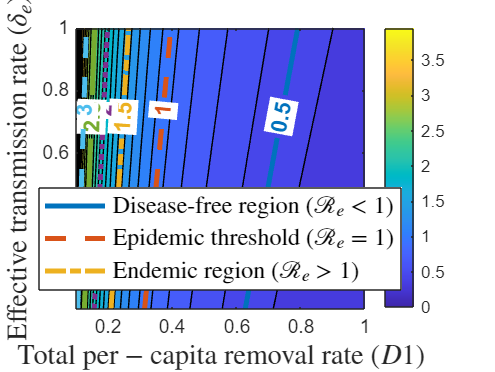


% Plot filled contours of R_e
contour_levels = linspace(min(Re_grid(:)), max(Re_grid(:)), 30);  
contourf(DI_grid, de_grid, Re_grid, contour_levels, 'LineWidth', 0.5);
colorbar;
colormap(parula); 
caxis([0 max(Re_grid(:))]); 
hold on;

% --- Define specific R_e levels to draw and label ---
label_levels = [0.2, 0.5, 1.0, 1.5, 2.0, 2.5, 3.0];
valid_levels = label_levels(label_levels >= min(Re_grid(:)) & label_levels <= max(Re_grid(:)));

% Prepare distinct colors and line styles for each level
colors = lines(length(valid_levels));
line_styles = {'-', '--', '-.', ':'};
n_styles = length(line_styles);

% Loop through each valid level to plot with distinct colors/styles and label them
for i = 1:length(valid_levels)
    level = valid_levels(i);
    
    % Get style for this level
    current_style = line_styles{mod(i-1, n_styles) + 1};
    
    % Plot the contour for this specific level
    [C, h] = contour(DI_grid, de_grid, Re_grid, [level level], ...
        'LineWidth', 2.5, 'Color', colors(i,:), 'LineStyle', current_style);
    
    % Check if the contour was actually drawn
    if ~isempty(h) && ~isempty(C)
        % Label the contour line with matching color and white background for readability
        clabel(C, h, 'FontSize', 11, 'FontWeight', 'bold', ...
            'Color', colors(i,:), 'BackgroundColor', 'w');
    end
end

% =========================================================================
% CREATE AN UNDERSTANDABLE GROUPED LEGEND
% =========================================================================
% Instead of listing every single contour line, we group them into 
% three biologically meaningful categories. We use dummy plot handles 
% to ensure the legend perfectly matches the colors/styles of the contours.

idx_less = find(valid_levels < 1.0, 1);
idx_eq   = find(valid_levels == 1.0, 1);
idx_gt   = find(valid_levels > 1.0, 1);

h_legend = [];
legend_labels = {};

% 1. Disease-free region (R_e < 1)
if ~isempty(idx_less)
    h_legend = [h_legend, plot(NaN, NaN, line_styles{mod(idx_less-1, n_styles)+1}, ...
        'Color', colors(idx_less,:), 'LineWidth', 2.5)];
    legend_labels{end+1} = 'Disease-free region ($\mathcal{R}_e < 1$)';
end

% 2. Epidemic threshold (R_e = 1)
if ~isempty(idx_eq)
    h_legend = [h_legend, plot(NaN, NaN, line_styles{mod(idx_eq-1, n_styles)+1}, ...
        'Color', colors(idx_eq,:), 'LineWidth', 2.5)];
    legend_labels{end+1} = 'Epidemic threshold ($\mathcal{R}_e = 1$)';
end

% 3. Endemic region (R_e > 1)
if ~isempty(idx_gt)
    h_legend = [h_legend, plot(NaN, NaN, line_styles{mod(idx_gt-1, n_styles)+1}, ...
        'Color', colors(idx_gt,:), 'LineWidth', 2.5)];
    legend_labels{end+1} = 'Endemic region ($\mathcal{R}_e > 1$)';
end

% UPDATED: Escaped underscore in D\_I to fix MATLAB syntax error
xlabel('Total per$-$capita removal rate ($D1$)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Effective transmission rate ($\delta_e$)', 'Interpreter', 'latex', 'FontSize', 14);

% Add the grouped legend to the plot
if ~isempty(h_legend)
    legend(h_legend, legend_labels, 'Interpreter', 'latex', 'Location', 'best', 'FontSize', 12);
end


%% --------------------- 6. Summary ----------------------------------------
fprintf('=== Summary ===\n');

=== Summary ===


fprintf('At DFE (I_T = 0, M = 0):  D_I = %.4f\n', D_I0);

At DFE (I_T = 0, M = 0):  D_I = 0.1000



% Simplified using the corrected common_term
fprintf('When I_T = 100, M = 0:    D_I = %.4f  =>  R_e = %.4f\n', ...
    D_I0 + gamma*rho*100*(2+sigma*100)/(1+sigma*100)^2, ...
    (epsilon/((D_I0 + gamma*rho*100*(2+sigma*100)/(1+sigma*100)^2)*(epsilon+mu))) ...
    * (delta_e + common_term));

When I_T = 100, M = 0:    D_I = 0.4889  =>  R_e = 0.7156



fprintf('When I_T = 0, M = 20:     D_I = %.4f  =>  R_e = %.4f\n', ...
    D_I0 + rho_M*20, ...
    (epsilon/((D_I0 + rho_M*20)*(epsilon+mu))) ...
    * (delta_e + common_term));

When I_T = 0, M = 20:     D_I = 0.7000  =>  R_e = 0.4998
